# **Practical 3 Setting up difference equations (Measles)**

## **PART I: Setting up difference equations**

Set up the SEIR model of the transmission dynamics of measles in a closed population using **difference equations**:        

We assume that individuals mix randomly and parameter values are given as follows: 

- Population 100,000 people

- Pre-infectious period 8 days

- Infectious period 7 days

- Basic reproduction number 13

- Life Expectancy 70 years

- Initial values (S,E,I,R)=(99999,0,1,0)

clear; close all; clc;

N = 100000;             % Population
pre_inf = 8;            % pre-infectious duration
D = 7;                  % infectious duration
R_0 = 13;               % reproduction number
LE = 70*365;      %L ife Expectancy

f = 1/pre_inf;
gamma = 1/D;
beta = R_0/(N*D);


## 1. Plot a graph for number of susceptible, pre-Infectious, infectious, and recovered populations during 200 days.

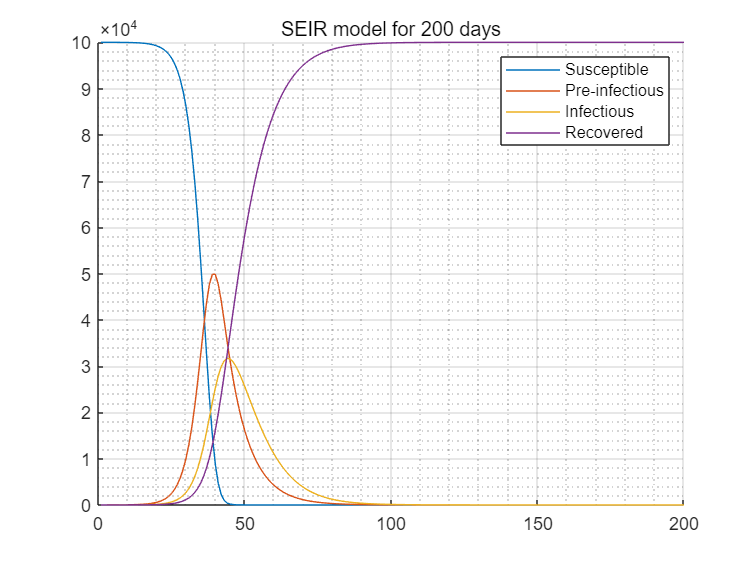

tspan = 200;
dt = 1;

% Allocate memories
S = zeros(tspan,1);
E = zeros(tspan,1);
I = zeros(tspan,1);
R = zeros(tspan,1);
% initial 
S(1) = 99999; 
E(1) = 0; 
I(1) = 1; 
R(1) = 0;

% Solve difference equation (DFE)
for i = 1:tspan-1
    S(i+1) = S(i) + (-beta * S(i) * I(i)) * dt;
    E(i+1) = E(i) + (beta * S(i) * I(i) - f * E(i)) * dt;
    I(i+1) = I(i) + (f * E(i) - gamma * I(i)) * dt;
    R(i+1) = R(i) + (gamma * I(i)) * dt;
end

% plot
figure(1)
time_stamp = 1:200;

hold on;
plot(time_stamp,S(:,1));
plot(time_stamp,E(:,1));
plot(time_stamp,I(:,1));
plot(time_stamp,R(:,1));
grid on; grid minor;
legend('Susceptible','Pre-infectious','Infectious','Recovered');
title('SEIR model for 200 days');
hold off;

## 2. How long does it take before there are no infectious persons in the population?Why do no further new infectious persons occur in this population after a certain time?

새로운 감염자가 137일 이후로 발생하지 않는 이유는 전파가 진행되며 Susceptible이 더 이상 없어 (New born도 없음) 감염시킬 인구가 사라졌기때문이다. 

[~,b] = max(I);% I의 최댓값 = a & "최댓값 위치 = b"
for i=b:tspan 
    if I(i)<1
        Free = i;
        break
    end
end
fprintf('전염병이 소멸되는 날짜는 %d일 후 입니다.\n',Free);

전염병이 소멸되는 날짜는 137일 후 입니다.


## 3. How does the graph change if you change the pre-infectious period to be 5 days and 20 days, respectively?

pre-infectious period가 길어질 수록 전염이 퍼지는 속도도 느려지며 전염병이 소명되는 날짜도 점점 늘어난다. 그리고 pre-infectious period가 길어질 수록 peak에서의 감염자의 최댓값이 점점 작아진다.

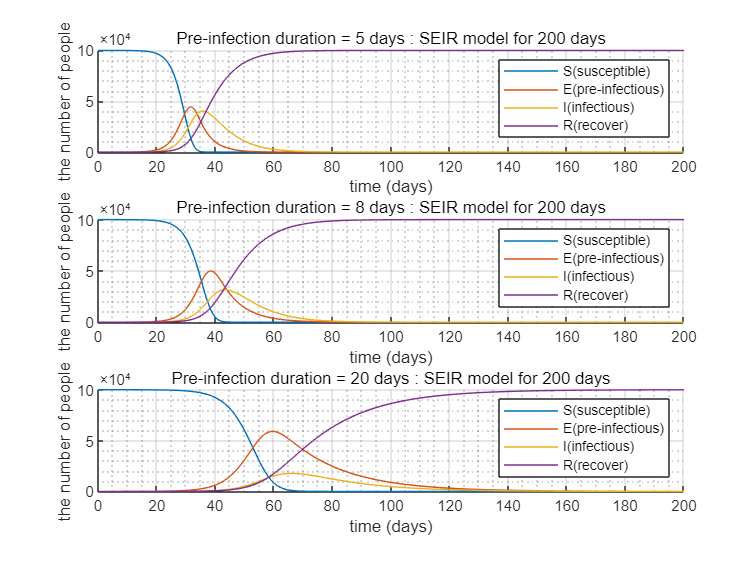


pre_inf = [5,8,20];
f_val = 1./pre_inf;

% Allocate memories
S = cell(1,length(f_val));
E = cell(1,length(f_val));
I = cell(1,length(f_val));
R = cell(1,length(f_val));

for j = 1:length(f_val)
    
    % Define time interval
    time_stamp = 1:dt:tspan+1;
    
    % Allocate memories
    S_temp = zeros(length(time_stamp), 1);
    E_temp = zeros(length(time_stamp), 1);
    I_temp = zeros(length(time_stamp), 1);
    R_temp = zeros(length(time_stamp), 1);
    
    % Initial states
    S_temp(1) = S0;
    E_temp(1) = E0;
    I_temp(1) = I0;
    R_temp(1) = R0;
    
    % Solve difference equation (DFE)
    for i = 1:dt:tspan+1
        S_temp(i+1) = S_temp(i) + (- beta .* I_temp(i) .* S_temp(i)) * dt;
        E_temp(i+1) = E_temp(i) + (beta .* I_temp(i) .* S_temp(i) - f_val(j) .* E_temp(i)) * dt;
        I_temp(i+1) = I_temp(i) + (f_val(j) .* E_temp(i) - gamma .* I_temp(i)) * dt;
        R_temp(i+1) = R_temp(i) + (gamma .* I_temp(i)) * dt;
    end
    
    S{1,j} = S_temp;
    E{1,j} = E_temp;
    I{1,j} = I_temp;
    R{1,j} = R_temp;
end
% plot
figure(2)
for i = 1:length(f_val)
    subplot(length(f_val),1,i) % 3*1 plot
    time_stamp = 0:dt:tspan+1;
    hold on;
    plot(time_stamp, S{1,i});
    plot(time_stamp, E{1,i});
    plot(time_stamp, I{1,i});
    plot(time_stamp, R{1,i});
    hold off;
    
    xlabel('time (days)')
    ylabel('the number of people')
    xlim([0 200])
    legend('S(susceptible)','E(pre-infectious)','I(infectious)','R(recover)')  
    grid on; grid minor;
    title(sprintf('Pre-infection duration = %d days : SEIR model for 200 days', pre_inf(i)))
end

# **PART Ⅱ: Incorporating births and deaths**

## 5. Assuming that the population size doesn’t change over time, what would be an appropriate expression for the per capita birth rate and death rate?

fprintf('PART Ⅱ: Incorporating births and deaths')

PART Ⅱ: Incorporating births and deaths

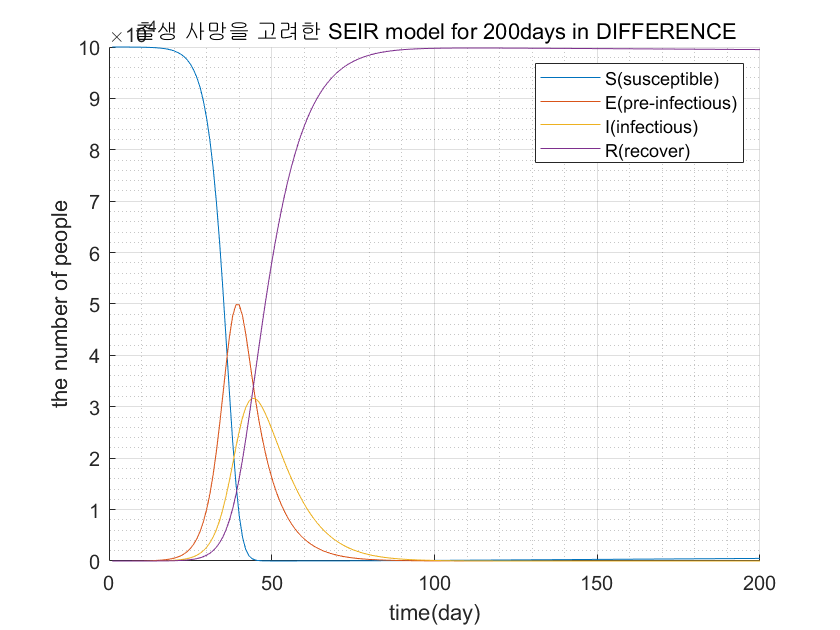

mu = 1/LE;
birth = N*mu; 
%Duration& unit time
tspan = 200; %(days)
dt= 1;

%Allocate memories
S = zeros(tspan,1); 
E = zeros(tspan,1); 
I = zeros(tspan,1); 
R = zeros(tspan,1);
S(1) = S0;E(1) = E0;I(1) = I0;R(1) = R0;

for i=1:tspan-1
    S(i+1) = S(i)+(birth-beta*I(i)*S(i)-mu*S(i))*dt;
    E(i+1) = E(i)+(beta*I(i)*S(i)-f*E(i)-mu*E(i))*dt;
    I(i+1) = I(i)+(f*E(i)-gamma*I(i)-mu*I(i))*dt;
    R(i+1) = R(i)+(gamma*I(i)-mu*R(i))*dt;
end

%plot 그리기
figure(3)
time_stamp = 1:dt:tspan;
hold on
plot(time_stamp,S(:,1))
plot(time_stamp,E(:,1))
plot(time_stamp,I(:,1))
plot(time_stamp,R(:,1))
hold off
xlabel('time(day)')
ylabel('the number of people')
grid on; grid minor;
title('출생 사망을 고려한 SEIR model for 200days in DIFFERENCE')
legend('S(susceptible)','E(pre-infectious)','I(infectious)','R(recover)') 

## 7-1. Is there a point where no more infections occur? 

[~,b] = max(I);
for i = b:tspan
    if I(i)<1
        Free = i;
        break
    end
end
fprintf('%d일째 감염자가 발생하지 않는다.\n',Free)

140일째 감염자가 발생하지 않는다.



for i = Free:tspan
    if I(i)>1
        Occur = i;
        fprintf('%d일째 다시 발생한다\n',Occur)
        break
    end
end


## 7-2. What about 10 years? 50 years?

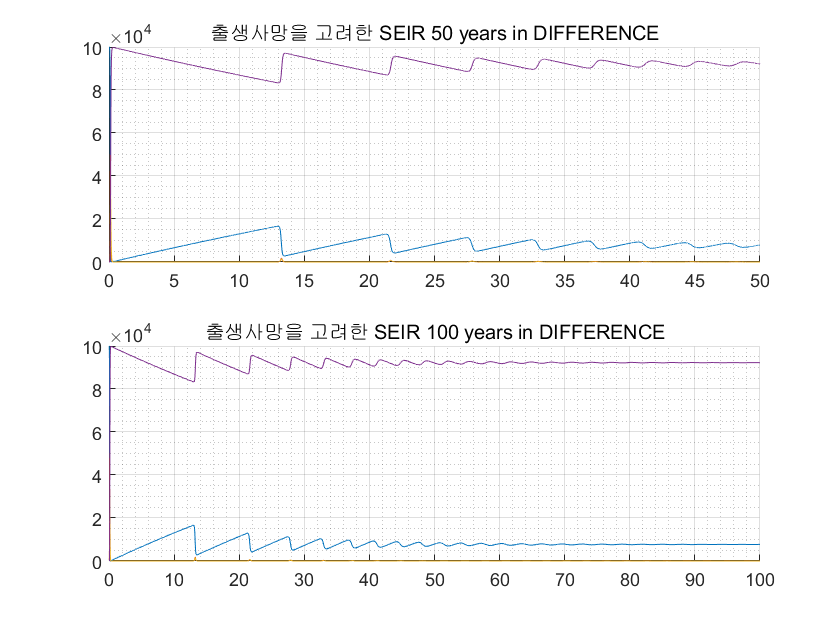

%Duration& unit time
tspan = [50*365 100*365]; %(days)
dt= 1;

%allocate memories
S = cell(1,length(tspan));
E = cell(1,length(tspan));
I = cell(1,length(tspan));
R = cell(1,length(tspan));

for j=1:length(tspan)
    
   S_temp = zeros(tspan(j),1);
   E_temp = zeros(tspan(j),1);
   I_temp = zeros(tspan(j),1);
   R_temp = zeros(tspan(j),1);
   
   S_temp(1)= S0;
   E_temp(1)= E0;
   I_temp(1)= I0;
   R_temp(1)= R0;
   
   for i=1:tspan(j)-1
    S_temp(i+1) = S_temp(i)+(birth-beta*I_temp(i)*S_temp(i)-mu*S_temp(i))*dt;
    E_temp(i+1) = E_temp(i)+(beta*I_temp(i)*S_temp(i)-f*E_temp(i)-mu*E_temp(i))*dt;
    I_temp(i+1) = I_temp(i)+(f*E_temp(i)-gamma*I_temp(i)-mu*I_temp(i))*dt;
    R_temp(i+1) = R_temp(i)+(gamma*I_temp(i)-mu*R_temp(i))*dt;
   end
    
   S{1,j} = S_temp;
   E{1,j} = E_temp;
   I{1,j} = I_temp;
   R{1,j} = R_temp;
end

%plot 그리기
figure(4)
for j = 1:length(tspan)
    t_stamp = 1:dt:tspan(j);
    subplot(2,1,j)
    hold on 
    plot(t_stamp./365,S{1,j})
    plot(t_stamp./365,E{1,j})
    plot(t_stamp./365,I{1,j})
    plot(t_stamp./365,R{1,j})
    hold off
    xlabel('time(year)')
    ylabel('the number of people')
    grid on; grid minor
    title(sprintf('출생사망을 고려한 SEIR %d years in DIFFERENCE',tspan(j)/365));
    
end

## 9. unit time을 2 3 4 5 10 로 바꿔보자 

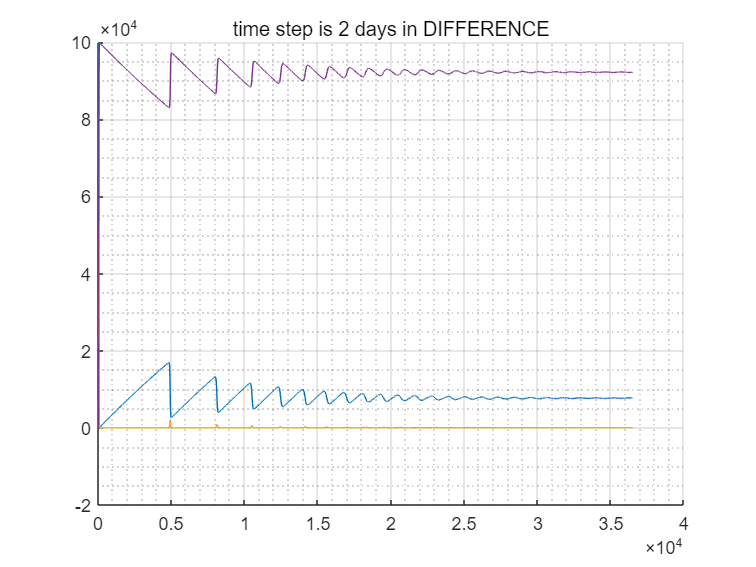

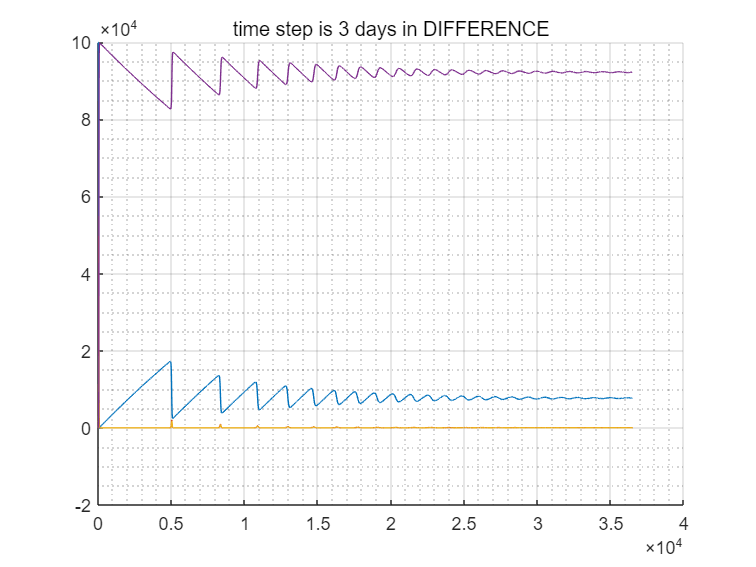

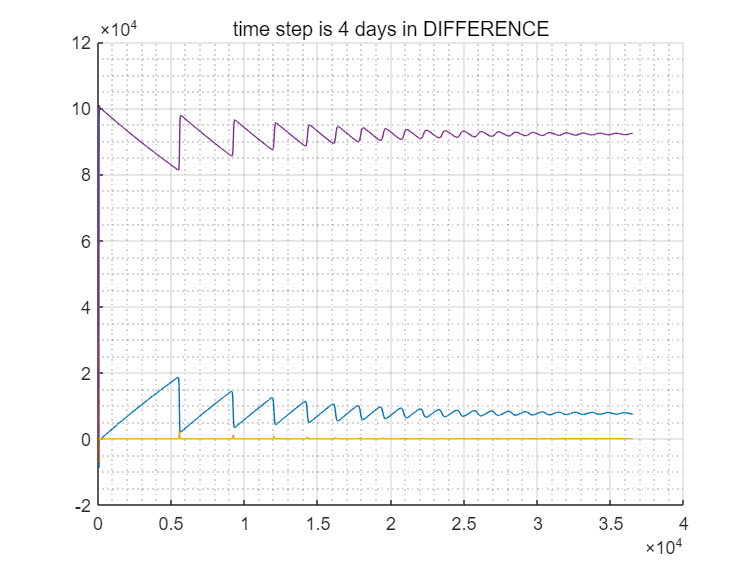

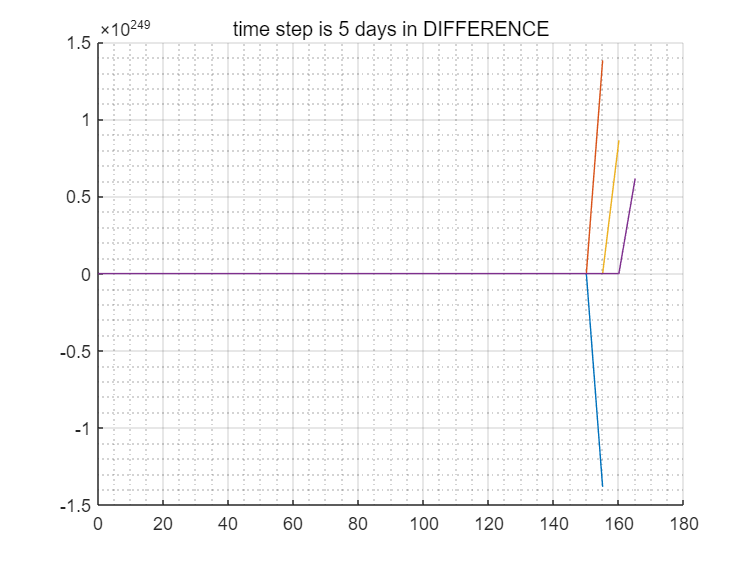

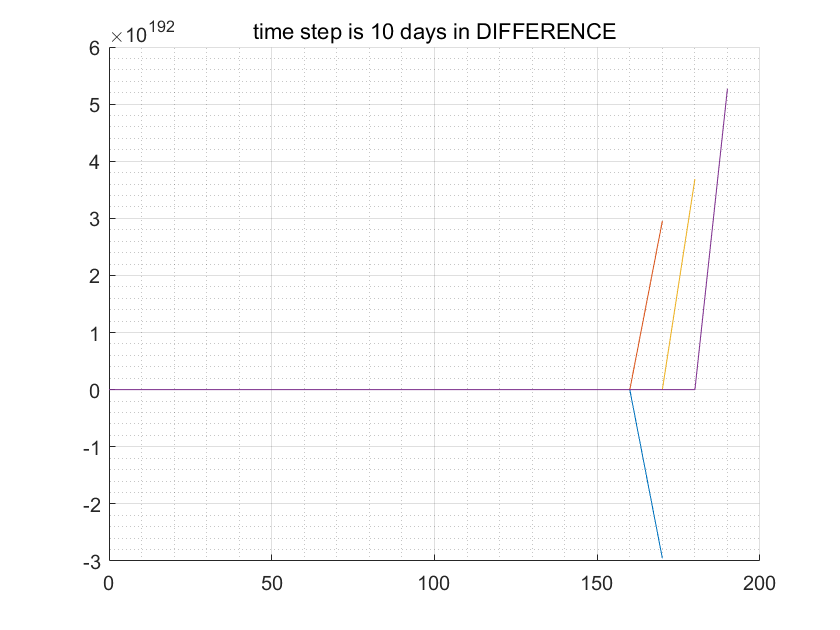

%Duration& unit time
tspan = 100*365; %(days)
dt= [2 3 4 5 10];

%allocate memories
S = cell(1,length(dt));
E = cell(1,length(dt));
I = cell(1,length(dt));
R = cell(1,length(dt));

for j=1:length(dt)
    t_stamp = 0:dt(j):tspan;
   S_temp = zeros(length(t_stamp),1);
   E_temp = zeros(length(t_stamp),1);
   I_temp = zeros(length(t_stamp),1);
   R_temp = zeros(length(t_stamp),1);
   
   S_temp(1)= S0;
   E_temp(1)= E0;
   I_temp(1)= I0;
   R_temp(1)= R0;
   %VARIABLE 조정%%%%%%%%여길 다시해봐야겠다
   
   for i=1:length(t_stamp)-1
    S_temp(i+1) = S_temp(i)+(birth-beta*I_temp(i)*S_temp(i)-mu*S_temp(i))*dt(j);
    E_temp(i+1) = E_temp(i)+(beta*I_temp(i)*S_temp(i)-f*E_temp(i)-mu*E_temp(i))*dt(j);
    I_temp(i+1) = I_temp(i)+(f*E_temp(i)-gamma*I_temp(i)-mu*I_temp(i))*dt(j);
    R_temp(i+1) = R_temp(i)+(gamma*I_temp(i)-mu*R_temp(i))*dt(j);
   end
    
   S{1,j} = S_temp;
   E{1,j} = E_temp;
   I{1,j} = I_temp;
   R{1,j} = R_temp;
end

%plot 그리기

for j = 1:length(dt)
    t_stamp = 0:dt(j):tspan;
    %subplot(5,1,j)
    figure(4+j)
    hold on 
    plot(t_stamp,S{1,j})
    plot(t_stamp,E{1,j})
    plot(t_stamp,I{1,j})
    plot(t_stamp,R{1,j})
    hold off
    grid on; grid minor
    title(sprintf('time step is %d days in DIFFERENCE',dt(j)));
end